Load data file (struct 3D format) and get axes order

path = 'vars\B5 b5 150um 4 A_struct_3D_desired_order_frequency_amplitude_offset';
data = load(path)

data = struct with fields:
    select_data_desired_order_3D: [1×1 struct]


varname = fieldnames(data);
data = data.(varname{1});
str_before_order = 'order_'; % input the string just before the first parameter
order = MFIA_get_order_from_path(path, str_before_order)

order = 1×3 cell array
    {'frequency'}    {'amplitude'}    {'offset'}


title = path(sum(find(path=='\', 1, 'last'))+1:sum(strfind(path, '_struct'))-1)

title = 'B5 b5 150um 4 A'

Select data to plot (leave empty to plot all data in 3D struct) and define plot aliases (from IA parametric model)

plt_select_data = {};
% plt_select_data(:,end+1) = {'param0'; 'Resistance [ohm]'};
plt_select_data(:,end+1) = {'param1'; 'Capacitance [F]'};

Select plot range

range = {};
range(:,end+1) = {'frequency'; [0 inf]};
range(:,end+1) = {'amplitude'; [0 inf]}; 
range(:,end+1) = {'offset'; [-inf inf]};

Define slice planes

slice_planes = {};
slice_planes(:,end+1) = {'frequency'; [1e2 1e3 1e4 1e5 5e5]};
slice_planes(:,end+1) = {'amplitude'; []}; 
slice_planes(:,end+1) = {'offset'; [0 -0.1 -0.2 -0.5 -1]};

Add plot formatting commands:

all: plt_cmds(2,end+1) =  {'comand'}; '' for ' inside string.

target: plt_cmds(:,end+1) =  {'target' ; 'comand'};

plt_cmds = {};
% plt_cmds(2,end+1) = {'grid on'};
plt_cmds(2,end+1) = {'colorbar(''eastoutside'')'};
plt_cmds(2,end+1) = {'colormap(s,''turbo'')'};
plt_cmds(2,end+1) = {'colormap(s,interp1(colormap(s), 1:(length(colormap(s))/998):length(colormap(s))))'};
plt_cmds(:,end+1) = {'param0'; 'colormap(s,[compress_array_exp(colormap(s),10,10, ''Reverse'', true, ''Interp'', true)])'};
plt_cmds(2,end+1) = {'colormap(s,[0 0 0; colormap(s)])'};
% plt_cmds(2,end+1) = {'colormap([colormap; 1 1 1])'};
plt_cmds(:,end+1) = {'param0'; 'caxis([0 1e6])'};
plt_cmds(:,end+1) = {'param1'; 'caxis([0 inf])'};

plt_log_freq = true; % true for log plot frequency
if plt_log_freq
    order{contains(order, 'frequency')} = 'log_frequency';
    range(:,contains(range(1,:), 'frequency')) = {'log_frequency'; log10(range{2,contains(range(1,:), 'frequency')})};
    slice_planes(:,contains(slice_planes(1,:), 'frequency')) = {'log_frequency'; log10(slice_planes{2,contains(slice_planes(1,:), 'frequency')})};
end

Plot slice planes of 3D data

[sbp, data_cell, axes_cell] = plot_struct_data3D(data, order, slice_planes, 'title', title, 'range', range, 'plt_select_data', plt_select_data, 'plt_cmds', plt_cmds);

Fit data along a certain dimension

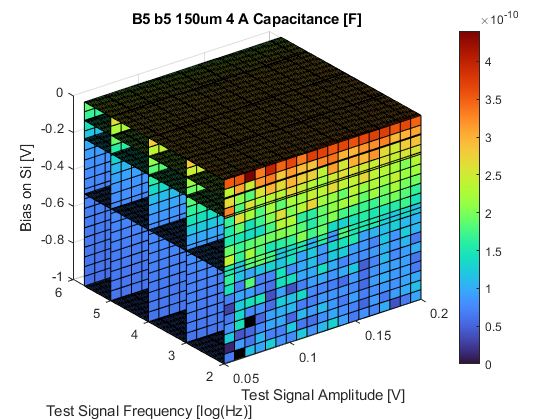

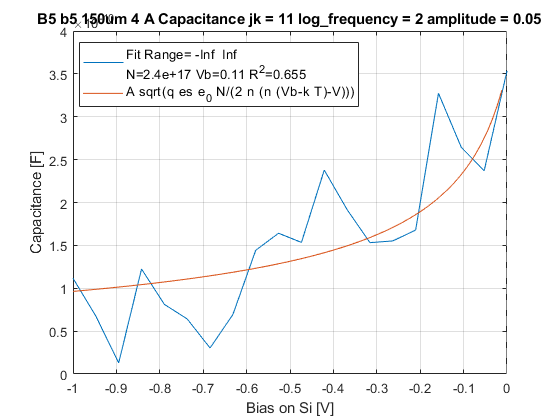

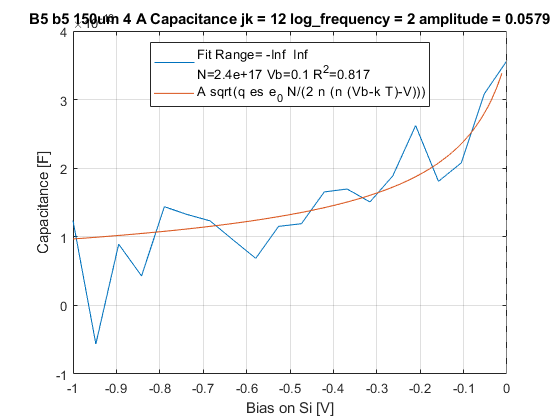

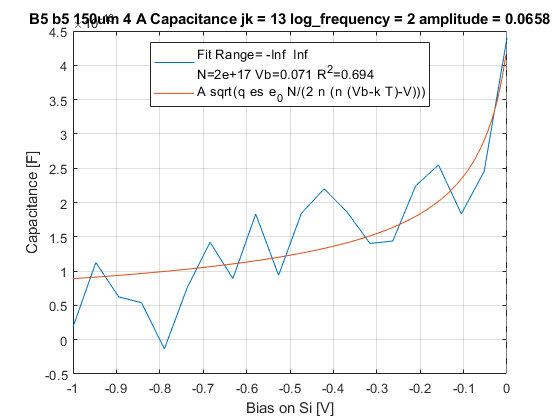

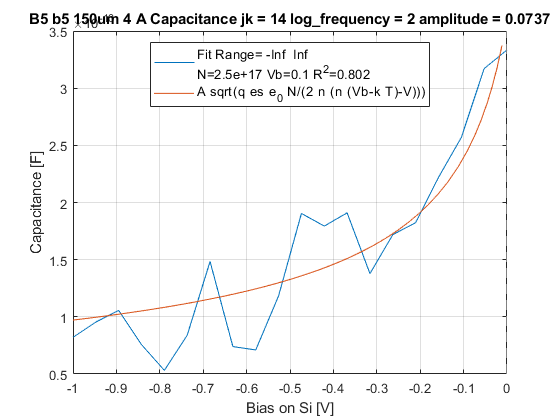

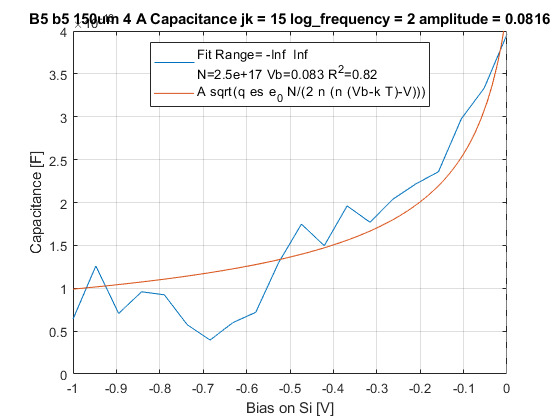

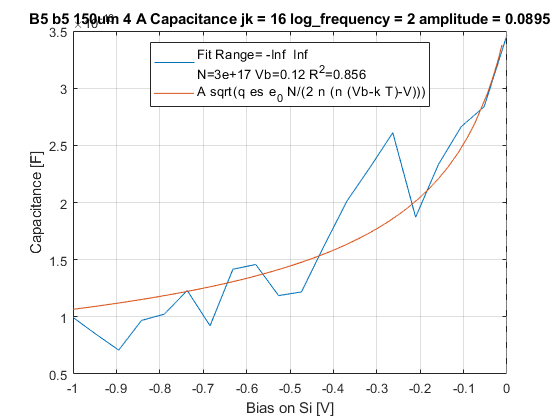

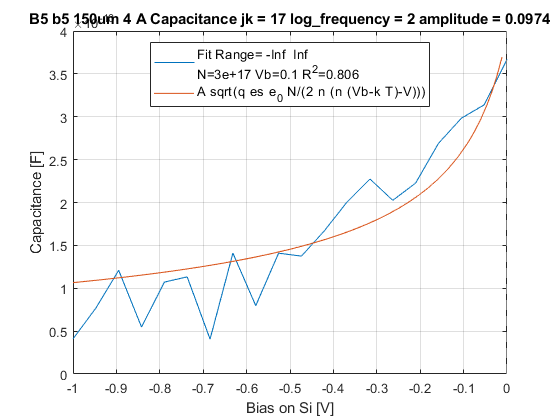

syms V N Vb n
limits_A = {'Vb',[0 0.5 1],'N',[1e17 2e18 5e18],'n',[1 9 10]};
n = 1;
fit_axis = 'offset';
es = 11.68;
A = (150^2 * pi)*1e-8;
range = [-inf inf];
fit_func = @(x,y) C_schot_fit_A(x,y,range,A,es,N,Vb,n);
plot_fit.func = @plot;
plot_fit.savepath = 'C:\Users\admin2\Documents\GitHub\mfiaDLTS\AcquireData\FrequencyAmplitudeBias_Sweep\vars';
fit_cell_3D(data_cell, axes_cell, fit_func, fit_axis, 'plt_select_data', plt_select_data, 'title', title, 'plot_fit', plot_fit);